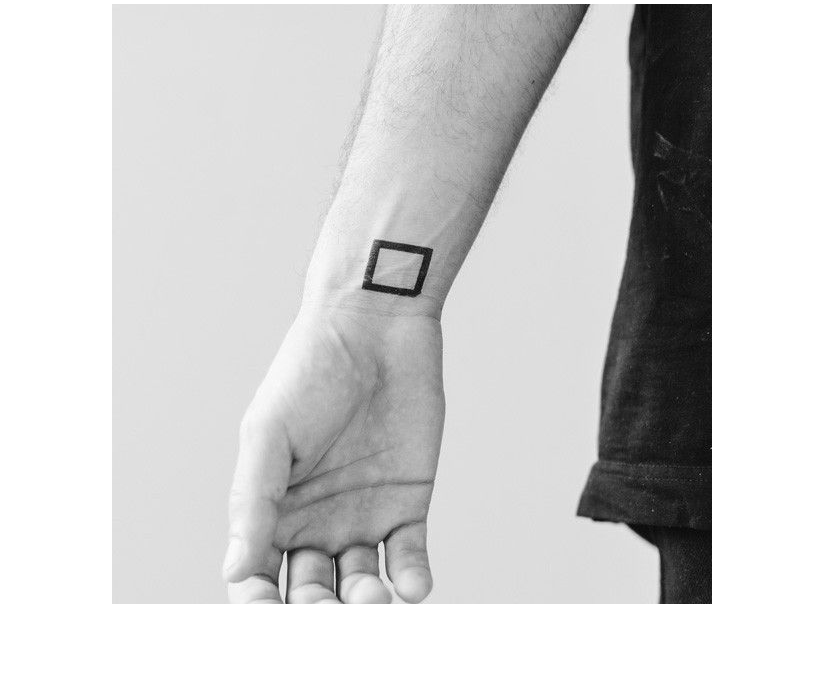

clc;
close all;
clear all;
im3=imread('/Users/aaditya/Downloads/im2.jpg');
im3=rgb2gray(im3);
imshow(im3)

im3=imrotate(im3,-180);
im2=im3;
figure(3)
canny_im3=edge(im3,"canny",0.4,0.2);
bw = imfill(canny_im3,"holes");

SE = strel("rectangle",[10 10]);
canny_im3=imdilate(bw,SE);
figure(5)

SE = strel("rectangle",[10 10]);
bw=imerode(bw,SE);


corner harris



corners= detectHarrisFeatures(bw)

corners =   22×1 cornerPoints array with properties:

    Location: [22×2 single]
      Metric: [22×1 single]
       Count: 22


t=corners.selectStrongest(4)

t =   4×1 cornerPoints array with properties:

    Location: [4×2 single]
      Metric: [4×1 single]
       Count: 4


cornerPoints=t.Location

cornerPoints = 4×2 single matrix
  333.4654  325.5684
  295.4878  344.2470
  302.3238  320.5203
  327.6762  349.4797


tatoo=imread('/Users/aaditya/Downloads/tat2.jpeg');
%tatoo=rgb2gray(tatoo);
tatoo=imresize(tatoo,[50,50]);
dst=([ 0,0 ; 600,0 ; 0,600 ; 600,600 ]);




% Determine the corners of the rectangle
topLeft=cornerPoints(3,:)

topLeft = 1×2 single row vector
  302.3238  320.5203


topRight=cornerPoints(1,:)

topRight = 1×2 single row vector
  333.4654  325.5684


bottomLeft=cornerPoints(2,:)

bottomLeft = 1×2 single row vector
  295.4878  344.2470


bottomRight=cornerPoints(4,:)

bottomRight = 1×2 single row vector
  327.6762  349.4797



src = [topLeft; topRight; bottomRight; bottomLeft];
%dst = single(t.Location)

tform = projective2d;

% Set the TransformationMatrix property of the transformation object
tform.T = fitgeotrans(src, dst, 'projective').T;
tform.T;
% Use imwarp to apply the transformation to your image (assuming 'img' is your image)
outputImage = imwarp(im3, tform);
tatoo=imread('/Users/aaditya/Downloads/tat4.jpeg');

%tatoo=rgb2gray(tatoo);

tatoo=tatoo>128;
tatoo=~(tatoo)

tatoo = 360×360 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

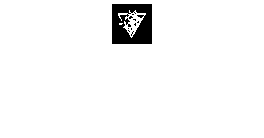

tatoo=imresize(tatoo,[40,40]);
imshow(tatoo)

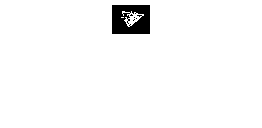

src=([ 0,0 ; 40,0 ; 0,40 ; 40,40 ]);
dst = [topLeft; topRight; bottomLeft; bottomRight];
tform = projective2d;

tform.T = fitgeotrans(src, dst, 'projective').T;

tform.T;
outputImage = imwarp(tatoo, tform);
imshow(outputImage)


[m,n]=size(outputImage)

m = 29

n = 38

max_size=max(m,n)

max_size = 38

max_size2=max_size+10

max_size2 = 48


bw3=bw;


outputImage=uint8(255 * mat2gray(outputImage))

outputImage = 29×38 uint8 matrix
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0   

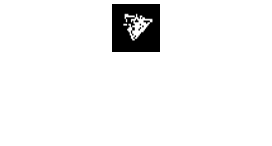


outputImage=imresize(outputImage,[max_size2,max_size2]);
imshow(outputImage)

im3=imread('/Users/aaditya/Downloads/im2.jpg');
im3=rgb2gray(im3);
im3=imrotate(im3,-180);

% Define the region where you want to paste outputImage
output_region = outputImage(1:40, 1:40);
output_region=output_region>128;
output_region=~output_region;

w=[0,0];
x=[600,0];
y=[0,600];
z=[600,600];

[a1,idx1]=min([norm(cornerPoints(1,:)-w),norm(cornerPoints(2,:)-w),norm(cornerPoints(3,:)-w),norm(cornerPoints(4,:)-w)]);
topLeft;
topLeft1=ceil(cornerPoints(idx1,:))

topLeft1 = 1×2 single row vector
   303   321


[a2,idx2]=min([norm(cornerPoints(1,:)-x),norm(cornerPoints(2,:)-x),norm(cornerPoints(3,:)-x),norm(cornerPoints(4,:)-x)]);
topRight;
topRight1=ceil(cornerPoints(idx2,:))

topRight1 = 1×2 single row vector
   334   326


[a3,idx3]=min([norm(cornerPoints(1,:)-y),norm(cornerPoints(2,:)-y),norm(cornerPoints(3,:)-y),norm(cornerPoints(4,:)-y)]);
bottomLeft;
bottomLeft1=ceil(cornerPoints(idx3,:))

bottomLeft1 = 1×2 single row vector
   296   345


[a4,idx4]=min([norm(cornerPoints(1,:)-z),norm(cornerPoints(2,:)-z),norm(cornerPoints(3,:)-z),norm(cornerPoints(4,:)-z)]);
bottomRight;
bottomRight1=ceil(cornerPoints(idx4,:))

bottomRight1 = 1×2 single row vector
   328   350



im3_region = im3(topLeft(2)-6:bottomRight(2)+5, bottomLeft1(1)-1:topRight1(1));

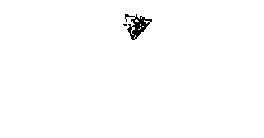

imshow(output_region)

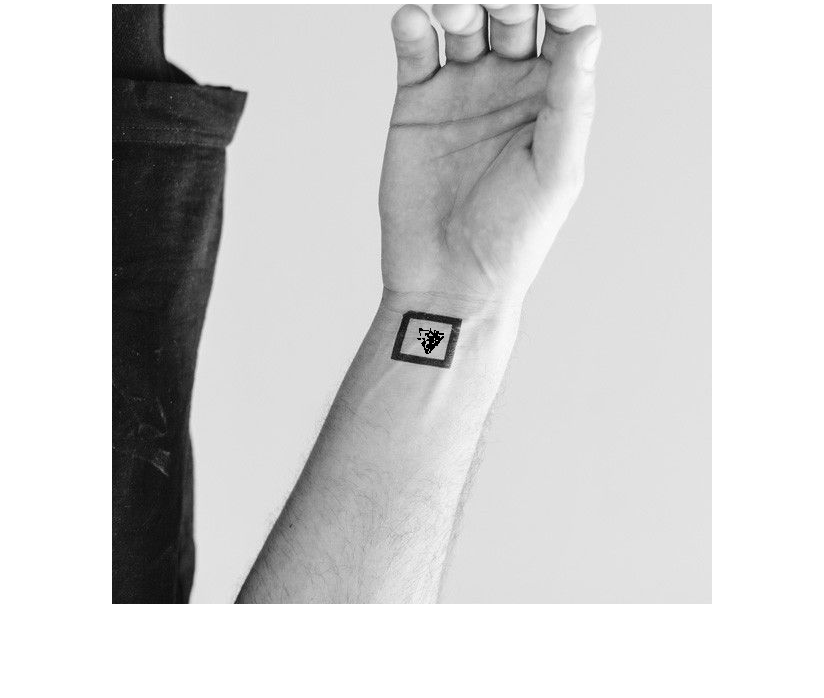

% Loop through the region and copy values using for loops
for x = 1: max_size
    for y = 1:max_size
        % Check if the value in outputImage is equal to 0 before copying
        if output_region(x, y) ==0
            im3_region(x, y) = output_region(x, y);
        end
    end
end


% Update the region in im3
im3(315:354, 295:334) = im3_region;
imshow(im3)